Konstanten (Längen/Massen)

syms F_vorne F_hinten alpha beta gamma;
l_mmp = 0.010029;        % Massenmittelpunkt [m]
l_heli = 0.655;          % Länge zu den beiden Rotoren [m]
l_rotor = 0.1775;        % Länge von der Drehachse zum Rotor [m]

g = 9.81;                % [m/s^2]
m_mmp = 3.960;           % Gesammte Masse [kg]

F_grav = m_mmp * g;      % Gravitationskraft die auf den gesamten Heli einwirkt (pos Z-Achse -> minus)

Motorkennlinie

U = [0.5 1 1.5 2 2.5 3 3.5 4]*3;        % (Spannung)
rot_vorne = [2 4 8 14 22 33 52 74];
rot_hinten = [2 4 8 14 24 35 55 72];

% Könnte man auch im mean nehmen, da die werde sich fast 1:1 entsprechen
% rot hinten zwischendurch größe, aber bei höheren V kleiner -> Messfehler
% der wage.

% mean der beiden nehmen
rot_mean = (rot_vorne + rot_hinten)/2;

% passendes polynom finden
p_mean = polyfit(U, rot_mean, 3);
fprintf('Polynom:  F = %.6f*U^3 + %.6f*U^2 + %.4f*U + %.4f\n', p_mean);

Polynom:  F = 0.030303*U^3 + 0.104618*U^2 + 0.4141*U + 1.0714


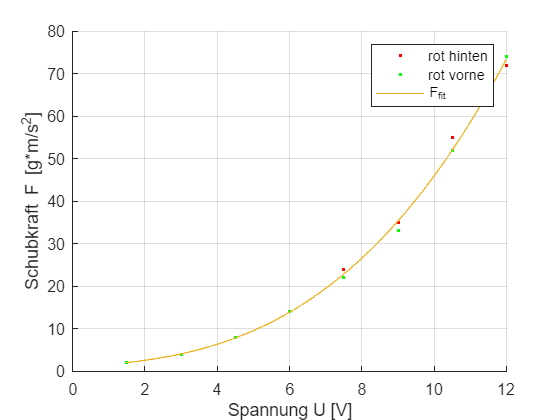


U_plot = linspace(min(U), max(U), 200);
F_fit = polyval(p_mean, U_plot);

figure
hold on
grid on
plot(schritte, rot_hinten, '.r', 'DisplayName', 'rot hinten');
plot(schritte, rot_vorne, '.g', 'DisplayName', 'rot vorne');
plot(U_plot, F_fit, 'DisplayName', 'F_fit');
xlabel('Spannung U [V]');
ylabel('Schubkraft F [g*m/s^{2}]');
legend show
hold off

Trägheitstensor

I_alpha = 1.130985;              % (heli+arm+halter | KOS um Drehachse)
I_beta = 0.576507 + 0.548608;    % (Trägheitstensor heli + ... arm | KOS Gelenk Arm)
I_gamma = 0.040229;              % (nur heli | KOS vorne)
I = [I_alpha   0       0;
     0       I_beta    0;
     0         0    I_gamma]

I =     1.1310         0         0
         0    1.1251         0
         0         0    0.0402


Bewegungsgleichungen

alpha_dd = (-(F_vorne+F_hinten)*l_heli*sin(gamma))/I_alpha

$$alpha\_dd = -\frac{1125899906842624\,\sin\left(\gamma \right)\,\left(\frac{131\,F_{\mathrm{hinten}}}{200}+\frac{131\,F_{\mathrm{vorne}}}{200}\right)}{1273375906140405}$$

beta_dd  = ((F_vorne+F_hinten)*l_heli*cos(gamma) - F_grav*l_mmp*cos(beta))/I_beta

$$beta\_dd = \frac{1125899906842624\,\cos\left(\gamma \right)\,\left(\frac{131\,F_{\mathrm{hinten}}}{200}+\frac{131\,F_{\mathrm{vorne}}}{200}\right)}{1266766873687239}-\frac{7018456143648095\,\cos\left(\beta \right)}{20268269978995824}$$

gamma_dd = ((F_vorne-F_hinten)*l_rotor)/I_gamma

$$gamma\_dd = \frac{319755573543305216\,F_{\mathrm{vorne}}}{72470123763795075}-\frac{319755573543305216\,F_{\mathrm{hinten}}}{72470123763795075}$$

Zustandsvektor

syms alpha alpha_d beta beta_d gamma gamma_d

x=[alpha;
   alpha_d;
   beta;
   beta_d;
   gamma;
   gamma_d];

u = [F_vorne;
     F_hinten];

x_d = [alpha_d; 
       alpha_dd;
       beta_d;
       beta_dd;
       gamma_d;
       gamma_dd];

A = jacobian(x_d, x)

$$A = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{1125899906842624\,\cos\left(\gamma \right)\,\sigma_{1}}{1273375906140405} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & \frac{7018456143648095\,\sin\left(\beta \right)}{20268269978995824} & 0 & -\frac{1125899906842624\,\sin\left(\gamma \right)\,\sigma_{1}}{1266766873687239} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{131\,F_{\mathrm{hinten}}}{200}+\frac{131\,F_{\mathrm{vorne}}}{200} \end{array}$$

B = jacobian(x_d, u)

$$B = \left(\begin{array}{cc} 0 & 0\\ -\frac{18436610974547968\,\sin\left(\gamma \right)}{31834397653510125} & -\frac{18436610974547968\,\sin\left(\gamma \right)}{31834397653510125}\\ 0 & 0\\ \frac{18436610974547968\,\cos\left(\gamma \right)}{31669171842180975} & \frac{18436610974547968\,\cos\left(\gamma \right)}{31669171842180975}\\ 0 & 0\\ \frac{319755573543305216}{72470123763795075} & -\frac{319755573543305216}{72470123763795075} \end{array}\right)$$


C = eye(6)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D = zeros(6, 2)

D =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
